clear
close all

Env = xlsread('S6_Metadata.xlsx'); 


IDXwinter = find (Env (:,2)==2);
winter=Env(IDXwinter,:);

IDXspring = find (Env (:,2)==4);
spring=Env(IDXspring,:);

IDXsummer = find (Env (:,2)==8);
summer=Env(IDXsummer,:);

dateW = winter (:,1:3);
dateS = spring (:,1:3);
dateSM = summer (:,1:3);

dateWN = datenum (dateW);
dateSN = datenum (dateS);
dateSMN = datenum (dateSM);



stW = winter (:,4);
stS = spring (:,4);
stSM = summer (:,4);

depthW = winter (:,5);
depthS = spring (:,5);
depthSM = summer (:,5);

NO2NW = winter (:,6);
NO3NW = winter (:,7);
NH4NW = winter (:,8);
TINW = winter (:,9);
PO4NW = winter (:,10);
SiO2NW = winter (:,11);
TChlaNW = winter (:,14);

NO2NS = spring (:,6);
NO3NS = spring (:,7);
NH4NS = spring (:,8);
TINS = spring (:,9);
PO4NS = spring (:,10);
SiO2NS = spring (:,11);
TChlaNS = spring (:,14);

NO2NSM = summer (:,6);
NO3NSM = summer (:,7);
NH4NSM = summer (:,8);
TINSM = summer (:,9);
PO4NSM = summer (:,10);
SiO2NSM = summer (:,11);
TChlaNSM = summer (:,14);


## Interpolacion


% %interpolacion de la variable x
dateINTW=[linspace(min(dateWN),max(dateWN),9)];%aquí empezarías tú, tendrías que poner tu variable x, que es distancia, no sé si lo tienes en longitud, imagino que si
dateINTS=[linspace(min(dateSN),max(dateSN),9)]

dateINTS = 	1.0e+05 *

    7.3642    7.3642    7.3642    7.3642    7.3642    7.3642    7.3643    7.3643    7.3643


dateINTSM=[linspace(min(dateSMN),max(dateSMN),9)]

dateINTSM = 	1.0e+05 *

    7.3654    7.3654    7.3654    7.3655    7.3655    7.3655    7.3655    7.3655    7.3655



presINT=(1:5:200)'; %creas tu variable profundidad según la prof maxima de tus estaciones. Por ejemplo si tu profundidad máxima es 100, pues creas la variable pres cada metro por ejemplo d ela siguiente forma: pres=(0:1:100)';

[x1d,y1d]=meshgrid(dateINTW,presINT); %creas una malla usando tu variable x (distancia) y tu variable y (profundidad)
[x2d,y2d]=meshgrid(dateINTS,presINT);
[x3d,y3d]=meshgrid(dateINTSM,presINT);
% Interpolacion dee las variables ambientales
%interpolas tu variable, en este caso el nitrato, sobre la malla que acabas de crear (yo le llame x1d e y1d al a malla)



## Interpolacion Winter


NO2_INT_W = gridfit(dateWN(isfinite(NO2NW)),depthW(isfinite(NO2NW)),NO2NW(isfinite(NO2NW)),x1d(1,:),y1d(:,1)); 

NO3_INT_W = gridfit(dateWN(isfinite(NO3NW)),depthW(isfinite(NO3NW)),NO3NW(isfinite(NO3NW)),x1d(1,:),y1d(:,1)); 

NH4_INT_W = gridfit(dateWN(isfinite(NH4NW)),depthW(isfinite(NH4NW)),NH4NW(isfinite(NH4NW)),x1d(1,:),y1d(:,1)); 

TIN_INT_W = gridfit(dateWN(isfinite(TINW)),depthW(isfinite(TINW)),TINW(isfinite(TINW)),x1d(1,:),y1d(:,1)); 

PO4_INT_W = gridfit(dateWN(isfinite(PO4NW)),depthW(isfinite(PO4NW)),PO4NW(isfinite(PO4NW)),x1d(1,:),y1d(:,1)); 

SiO2_INT_W = gridfit(dateWN(isfinite(SiO2NW)),depthW(isfinite(SiO2NW)),SiO2NW(isfinite(SiO2NW)),x1d(1,:),y1d(:,1)); 

TChla_INT_W = gridfit(dateWN(isfinite(TChlaNW)),depthW(isfinite(TChlaNW)),TChlaNW(isfinite(TChlaNW)),x1d(1,:),y1d(:,1)); 



NO2_INT_S = gridfit(dateSN(isfinite(NO2NS)),depthS(isfinite(NO2NS)),NO2NS(isfinite(NO2NS)),x2d(1,:),y2d(:,1)); 

NO3_INT_S = gridfit(dateSN(isfinite(NO3NS)),depthS(isfinite(NO3NS)),NO3NS(isfinite(NO3NS)),x2d(1,:),y2d(:,1)); 

NH4_INT_S = gridfit(dateSN(isfinite(NH4NS)),depthS(isfinite(NH4NS)),NH4NS(isfinite(NH4NS)),x2d(1,:),y2d(:,1)); 

TIN_INT_S = gridfit(dateSN(isfinite(TINS)),depthS(isfinite(TINS)),TINS(isfinite(TINS)),x2d(1,:),y2d(:,1)); 

PO4_INT_S = gridfit(dateSN(isfinite(PO4NS)),depthS(isfinite(PO4NS)),PO4NS(isfinite(PO4NS)),x2d(1,:),y2d(:,1)); 

SiO2_INT_S = gridfit(dateSN(isfinite(SiO2NS)),depthS(isfinite(SiO2NS)),SiO2NS(isfinite(SiO2NS)),x2d(1,:),y2d(:,1)); 

TChla_INT_S = gridfit(dateSN(isfinite(TChlaNS)),depthS(isfinite(TChlaNS)),TChlaNS(isfinite(TChlaNS)),x2d(1,:),y2d(:,1)); 



NO2_INT_SM = gridfit(dateSMN(isfinite(NO2NSM)),depthSM(isfinite(NO2NSM)),NO2NSM(isfinite(NO2NSM)),x3d(1,:),y3d(:,1)); 

NO3_INT_SM = gridfit(dateSMN(isfinite(NO3NSM)),depthSM(isfinite(NO3NSM)),NO3NSM(isfinite(NO3NSM)),x3d(1,:),y3d(:,1)); 

NH4_INT_SM = gridfit(dateSMN(isfinite(NH4NSM)),depthSM(isfinite(NH4NSM)),NH4NSM(isfinite(NH4NSM)),x3d(1,:),y3d(:,1)); 

TIN_INT_SM = gridfit(dateSMN(isfinite(TINSM)),depthSM(isfinite(TINSM)),TINSM(isfinite(TINSM)),x3d(1,:),y3d(:,1)); 

PO4_INT_SM = gridfit(dateSMN(isfinite(PO4NSM)),depthSM(isfinite(PO4NSM)),PO4NSM(isfinite(PO4NSM)),x3d(1,:),y3d(:,1)); 

SiO2_INT_SM = gridfit(dateSMN(isfinite(SiO2NSM)),depthSM(isfinite(SiO2NSM)),SiO2NSM(isfinite(SiO2NSM)),x3d(1,:),y3d(:,1)); 

TChla_INT_SM = gridfit(dateSMN(isfinite(TChlaNSM)),depthSM(isfinite(TChlaNSM)),TChlaNSM(isfinite(TChlaNSM)),x3d(1,:),y3d(:,1)); 

## Figurras invierno

## NO2

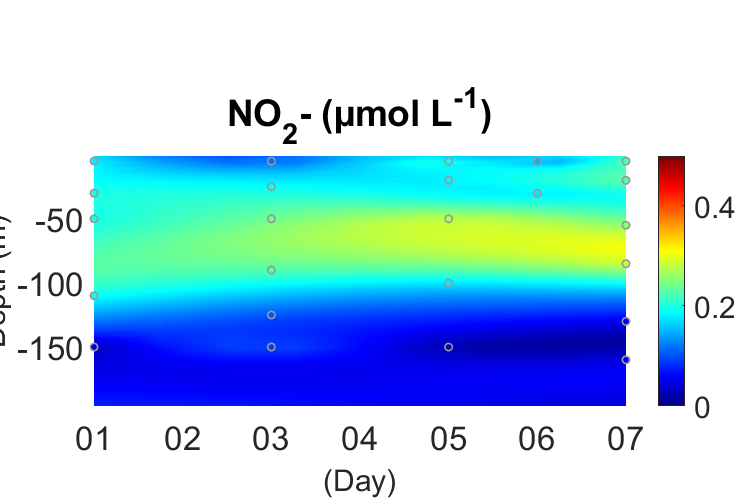

figure()

set(gcf,'PaperUnits','centimeters');
xSize=12; % Ancho
ySize=8; % Alto
xLeft=(12-xSize)/2;
yTop=(12-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

xt=1.5/xSize;
yt=1.5/ySize;
wt=(10)/xSize; % Ancho
ht=(4)/ySize; % Alto
axes('position',[xt yt wt ht]);

pcolor(dateINTW,-presINT,NO2_INT_W); %representas tu variable. primero colocas x(en mi caso date, que es el tiempo), luego y (en mi caso la presión en negativo) y luego tu variable de color (mi caso nitrato)
% shading flat; %esto es para que no te pinte una malla de cuadrados negros, así se ve más fluido el gráfico (hay otro que es interp en lugar de flat que lo suaviza mas aun)
shading interp
datetick('x','dd'); %esto tu no lo pones, porque no tienes tiempo en el eje x. para ver cómo se ponen las etiquetas, vete al otro que te pasé, al de cris
% xlim([dateN_I01(1)-0.008 dateN_I01(end)+0.08]); %esto no hace falta, es para eliminar huecos en blanco alrededor del gráfico. lo ajustas al valor máximo y mínimo de tus variables x e y
% ylim([-34.5 0]);

title ({'NO_{2}^ - (µmol L^-^1)'});
ax=gca;
ax.FontSize = 20;
ylabel('Depth (m)', 'FontSize',18); %nombre de los ejes
xlab=xlabel('(Day)', 'FontSize',18);

colormap('jet');
cb=colorbar;
caxis([0 0.5]);  % masximos y minomos de la escala

hold on; %para superponer los puntos donde se cogió muestra de agua para medir nitrato:
scatter(dateWN(isfinite(NO2NW)),-depthW(isfinite(NO2NW)),20,NO2NW(isfinite(NO2NW)),'o','filled','MarkerEdgeColor',[.6 .6 .6],'LineWidth',1);

exportgraphics(gcf, 'Winter_S6_NO2.png','Resolution',300)

## NO3

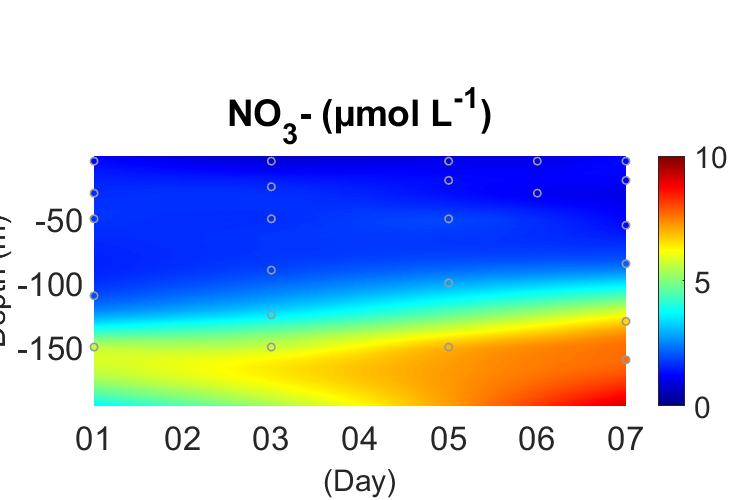

figure()

set(gcf,'PaperUnits','centimeters');
xSize=12; % Ancho
ySize=8; % Alto
xLeft=(12-xSize)/2;
yTop=(12-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

xt=1.5/xSize;
yt=1.5/ySize;
wt=(10)/xSize; % Ancho
ht=(4)/ySize; % Alto
axes('position',[xt yt wt ht]);

pcolor(dateINTW,-presINT,NO3_INT_W); %representas tu variable. primero colocas x(en mi caso date, que es el tiempo), luego y (en mi caso la presión en negativo) y luego tu variable de color (mi caso nitrato)
% shading flat; %esto es para que no te pinte una malla de cuadrados negros, así se ve más fluido el gráfico (hay otro que es interp en lugar de flat que lo suaviza mas aun)
shading interp
datetick('x','dd'); %esto tu no lo pones, porque no tienes tiempo en el eje x. para ver cómo se ponen las etiquetas, vete al otro que te pasé, al de cris
% xlim([dateN_I01(1)-0.008 dateN_I01(end)+0.08]); %esto no hace falta, es para eliminar huecos en blanco alrededor del gráfico. lo ajustas al valor máximo y mínimo de tus variables x e y
% ylim([-34.5 0]);

title ({'NO_{3}^ - (µmol L^-^1)'});
ax=gca;
ax.FontSize = 20;
ylabel('Depth (m)', 'FontSize',18); %nombre de los ejes
xlab=xlabel('(Day)', 'FontSize',18);

colormap('jet'); 
cb=colorbar;
caxis([0 10]);  % masximos y minomos de la escala

hold on; %para superponer los puntos donde se cogió muestra de agua para medir nitrato:
scatter(dateWN(isfinite(NO3NW)),-depthW(isfinite(NO3NW)),20,NO3NW(isfinite(NO3NW)),'o','filled','MarkerEdgeColor',[.6 .6 .6],'LineWidth',1);

exportgraphics(gcf, 'Winter_S6_NO3.png','Resolution',300)

## NH4

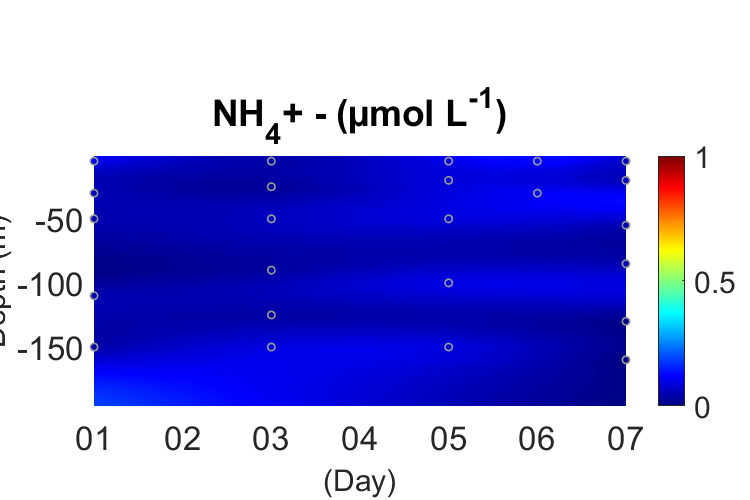

figure()

set(gcf,'PaperUnits','centimeters');
xSize=12; % Ancho
ySize=8; % Alto
xLeft=(12-xSize)/2;
yTop=(12-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

xt=1.5/xSize;
yt=1.5/ySize;
wt=(10)/xSize; % Ancho
ht=(4)/ySize; % Alto
axes('position',[xt yt wt ht]);

pcolor(dateINTW,-presINT,NH4_INT_W); %representas tu variable. primero colocas x(en mi caso date, que es el tiempo), luego y (en mi caso la presión en negativo) y luego tu variable de color (mi caso nitrato)
% shading flat; %esto es para que no te pinte una malla de cuadrados negros, así se ve más fluido el gráfico (hay otro que es interp en lugar de flat que lo suaviza mas aun)
shading interp
datetick('x','dd'); %esto tu no lo pones, porque no tienes tiempo en el eje x. para ver cómo se ponen las etiquetas, vete al otro que te pasé, al de cris
% xlim([dateN_I01(1)-0.008 dateN_I01(end)+0.08]); %esto no hace falta, es para eliminar huecos en blanco alrededor del gráfico. lo ajustas al valor máximo y mínimo de tus variables x e y
% ylim([-34.5 0]);

title ({'NH_{4}^ + - (µmol L^-^1)'});
ax=gca;
ax.FontSize = 20;
ylabel('Depth (m)', 'FontSize',18); %nombre de los ejes
xlab=xlabel('(Day)', 'FontSize',18);

colormap('jet'); cb=colorbar;
caxis([0 1]);  % masximos y minomos de la escala

hold on; %para superponer los puntos donde se cogió muestra de agua para medir nitrato:
scatter(dateWN(isfinite(NH4NW)),-depthW(isfinite(NH4NW)),20,NH4NW(isfinite(NH4NW)),'o','filled','MarkerEdgeColor',[.6 .6 .6],'LineWidth',1);

exportgraphics(gcf, 'Winter_S6_NH4.png','Resolution',300)

## TIN

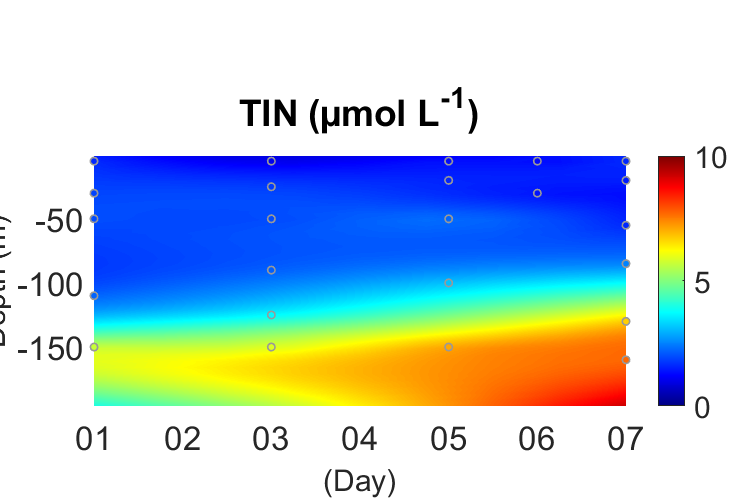

figure()

set(gcf,'PaperUnits','centimeters');
xSize=12; % Ancho
ySize=8; % Alto
xLeft=(12-xSize)/2;
yTop=(12-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

xt=1.5/xSize;
yt=1.5/ySize;
wt=(10)/xSize; % Ancho
ht=(4)/ySize; % Alto
axes('position',[xt yt wt ht]);

pcolor(dateINTW,-presINT,TIN_INT_W); %representas tu variable. primero colocas x(en mi caso date, que es el tiempo), luego y (en mi caso la presión en negativo) y luego tu variable de color (mi caso nitrato)
% shading flat; %esto es para que no te pinte una malla de cuadrados negros, así se ve más fluido el gráfico (hay otro que es interp en lugar de flat que lo suaviza mas aun)
shading interp
datetick('x','dd'); %esto tu no lo pones, porque no tienes tiempo en el eje x. para ver cómo se ponen las etiquetas, vete al otro que te pasé, al de cris
% xlim([dateN_I01(1)-0.008 dateN_I01(end)+0.08]); %esto no hace falta, es para eliminar huecos en blanco alrededor del gráfico. lo ajustas al valor máximo y mínimo de tus variables x e y
% ylim([-34.5 0]);

title ({'TIN_{ }(µmol L^-^1)'});
ax=gca;
ax.FontSize = 20;
ylabel('Depth (m)', 'FontSize',18); %nombre de los ejes
xlab=xlabel('(Day)', 'FontSize',18);

colormap('jet'); cb=colorbar;
caxis([0 10]);  % masximos y minomos de la escala

hold on; %para superponer los puntos donde se cogió muestra de agua para medir nitrato:
scatter(dateWN(isfinite(TINW)),-depthW(isfinite(TINW)),20,TINW(isfinite(TINW)),'o','filled','MarkerEdgeColor',[.6 .6 .6],'LineWidth',1);

exportgraphics(gcf, 'Winter_S6_TIN.png','Resolution',300)

## PO4

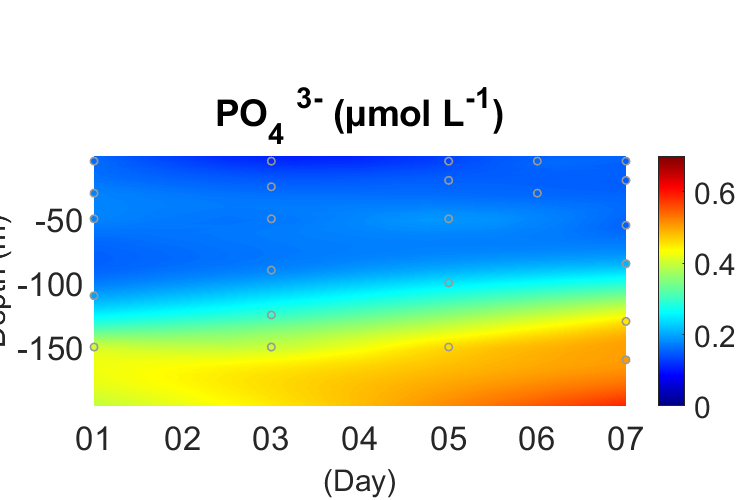

figure()

set(gcf,'PaperUnits','centimeters');
xSize=12; % Ancho
ySize=8; % Alto
xLeft=(12-xSize)/2;
yTop=(12-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

xt=1.5/xSize;
yt=1.5/ySize;
wt=(10)/xSize; % Ancho
ht=(4)/ySize; % Alto
axes('position',[xt yt wt ht]);

pcolor(dateINTW,-presINT,PO4_INT_W); %representas tu variable. primero colocas x(en mi caso date, que es el tiempo), luego y (en mi caso la presión en negativo) y luego tu variable de color (mi caso nitrato)
% shading flat; %esto es para que no te pinte una malla de cuadrados negros, así se ve más fluido el gráfico (hay otro que es interp en lugar de flat que lo suaviza mas aun)
shading interp
datetick('x','dd'); %esto tu no lo pones, porque no tienes tiempo en el eje x. para ver cómo se ponen las etiquetas, vete al otro que te pasé, al de cris
% xlim([dateN_I01(1)-0.008 dateN_I01(end)+0.08]); %esto no hace falta, es para eliminar huecos en blanco alrededor del gráfico. lo ajustas al valor máximo y mínimo de tus variables x e y
% ylim([-34.5 0]);

title ({'PO_{4} ^3^- (µmol L^-^1)'});
ax=gca;
ax.FontSize = 20;
ylabel('Depth (m)', 'FontSize',18); %nombre de los ejes
xlab=xlabel('(Day)', 'FontSize',18);

colormap('jet'); cb=colorbar;
caxis([0 0.7]);  % masximos y minomos de la escala

hold on; %para superponer los puntos donde se cogió muestra de agua para medir nitrato:
scatter(dateWN(isfinite(PO4NW)),-depthW(isfinite(PO4NW)),20,PO4NW(isfinite(PO4NW)),'o','filled','MarkerEdgeColor',[.6 .6 .6],'LineWidth',1);

exportgraphics(gcf, 'Winter_S6_PO4.png','Resolution',300)

## SiO2

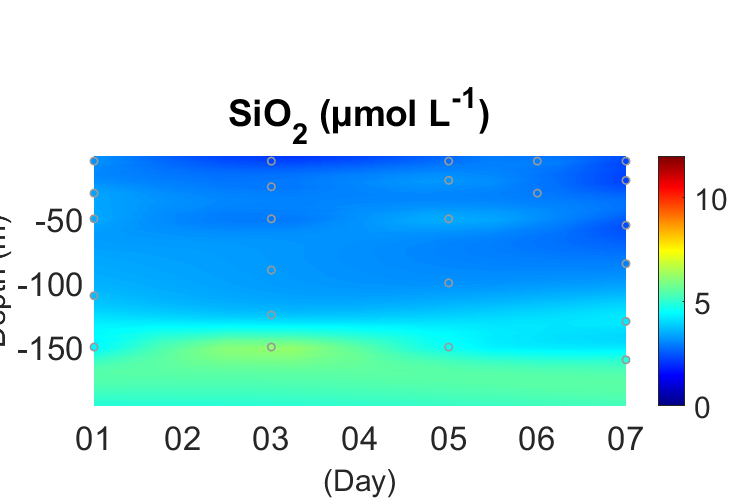

figure()

set(gcf,'PaperUnits','centimeters');
xSize=12; % Ancho
ySize=8; % Alto
xLeft=(12-xSize)/2;
yTop=(12-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

xt=1.5/xSize;
yt=1.5/ySize;
wt=(10)/xSize; % Ancho
ht=(4)/ySize; % Alto
axes('position',[xt yt wt ht]);

pcolor(dateINTW,-presINT,SiO2_INT_W); %representas tu variable. primero colocas x(en mi caso date, que es el tiempo), luego y (en mi caso la presión en negativo) y luego tu variable de color (mi caso nitrato)
% shading flat; %esto es para que no te pinte una malla de cuadrados negros, así se ve más fluido el gráfico (hay otro que es interp en lugar de flat que lo suaviza mas aun)
shading interp
datetick('x','dd'); %esto tu no lo pones, porque no tienes tiempo en el eje x. para ver cómo se ponen las etiquetas, vete al otro que te pasé, al de cris
% xlim([dateN_I01(1)-0.008 dateN_I01(end)+0.08]); %esto no hace falta, es para eliminar huecos en blanco alrededor del gráfico. lo ajustas al valor máximo y mínimo de tus variables x e y
% ylim([-34.5 0]);

title ({'SiO_{2} (µmol L^-^1)'});
ax=gca;
ax.FontSize = 20;
ylabel('Depth (m)', 'FontSize',18); %nombre de los ejes
xlab=xlabel('(Day)', 'FontSize',18);

colormap('jet'); cb=colorbar;
caxis([0 12]);  % masximos y minomos de la escala

hold on; %para superponer los puntos donde se cogió muestra de agua para medir nitrato:
scatter(dateWN(isfinite(SiO2NW)),-depthW(isfinite(SiO2NW)),20,SiO2NW(isfinite(SiO2NW)),'o','filled','MarkerEdgeColor',[.6 .6 .6],'LineWidth',1);

exportgraphics(gcf, 'Winter_S6_SiO2.png','Resolution',300)

## Clorofola Total

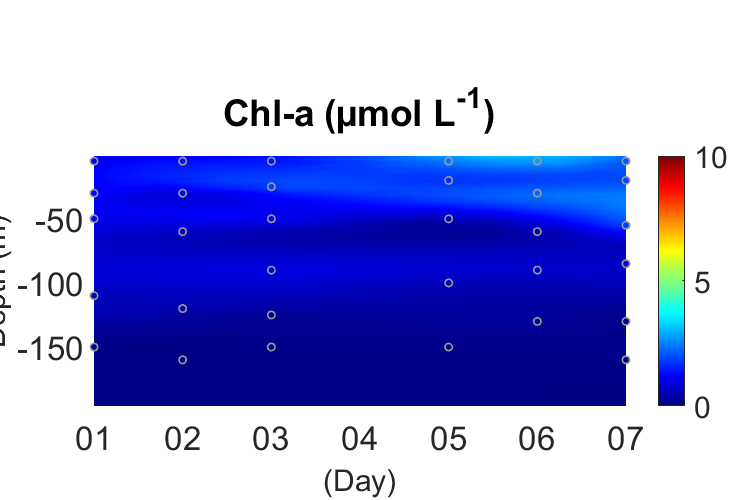

figure()

set(gcf,'PaperUnits','centimeters');
xSize=12; % Ancho
ySize=8; % Alto
xLeft=(12-xSize)/2;
yTop=(12-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

xt=1.5/xSize;
yt=1.5/ySize;
wt=(10)/xSize; % Ancho
ht=(4)/ySize; % Alto
axes('position',[xt yt wt ht]);

pcolor(dateINTW,-presINT,TChla_INT_W); %representas tu variable. primero colocas x(en mi caso date, que es el tiempo), luego y (en mi caso la presión en negativo) y luego tu variable de color (mi caso nitrato)
% shading flat; %esto es para que no te pinte una malla de cuadrados negros, así se ve más fluido el gráfico (hay otro que es interp en lugar de flat que lo suaviza mas aun)
shading interp
datetick('x','dd'); %esto tu no lo pones, porque no tienes tiempo en el eje x. para ver cómo se ponen las etiquetas, vete al otro que te pasé, al de cris
% xlim([dateN_I01(1)-0.008 dateN_I01(end)+0.08]); %esto no hace falta, es para eliminar huecos en blanco alrededor del gráfico. lo ajustas al valor máximo y mínimo de tus variables x e y
% ylim([-34.5 0]);

title ({'Chl-a_{ }(µmol L^-^1)'});
ax=gca;
ax.FontSize = 20;
ylabel('Depth (m)', 'FontSize',18); %nombre de los ejes
xlab=xlabel('(Day)', 'FontSize',18);

colormap('jet'); cb=colorbar;
caxis([0 10]);  % masximos y minomos de la escala

hold on; %para superponer los puntos donde se cogió muestra de agua para medir nitrato:
scatter(dateWN(isfinite(TChlaNW)),-depthW(isfinite(TChlaNW)),20,TChlaNW(isfinite(TChlaNW)),'o','filled','MarkerEdgeColor',[.6 .6 .6],'LineWidth',1);

exportgraphics(gcf, 'Winter_S6_Chl-a.png','Resolution',300)

## Spring

## NO2

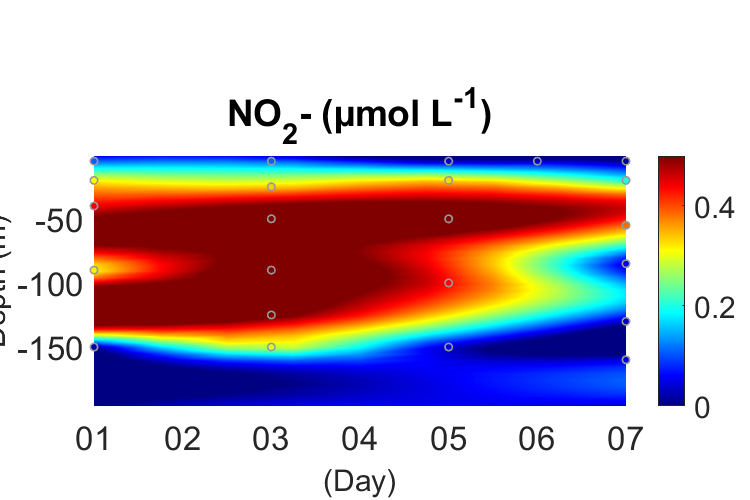

figure()

set(gcf,'PaperUnits','centimeters');
xSize=12; % Ancho
ySize=8; % Alto
xLeft=(12-xSize)/2;
yTop=(12-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

xt=1.5/xSize;
yt=1.5/ySize;
wt=(10)/xSize; % Ancho
ht=(4)/ySize; % Alto
axes('position',[xt yt wt ht]);

pcolor(dateINTS,-presINT,NO2_INT_S); %representas tu variable. primero colocas x(en mi caso date, que es el tiempo), luego y (en mi caso la presión en negativo) y luego tu variable de color (mi caso nitrato)
% shading flat; %esto es para que no te pinte una malla de cuadrados negros, así se ve más fluido el gráfico (hay otro que es interp en lugar de flat que lo suaviza mas aun)
shading interp
datetick('x','dd'); %esto tu no lo pones, porque no tienes tiempo en el eje x. para ver cómo se ponen las etiquetas, vete al otro que te pasé, al de cris
% xlim([dateN_I01(1)-0.008 dateN_I01(end)+0.08]); %esto no hace falta, es para eliminar huecos en blanco alrededor del gráfico. lo ajustas al valor máximo y mínimo de tus variables x e y
% ylim([-34.5 0]);

title ({'NO_{2}^ - (µmol L^-^1)'});
ax=gca;
ax.FontSize = 20;
ylabel('Depth (m)', 'FontSize',18); %nombre de los ejes
xlab=xlabel('(Day)', 'FontSize',18);

colormap('jet'); cb=colorbar;
caxis([0 0.5]);  % masximos y minomos de la escala

hold on; %para superponer los puntos donde se cogió muestra de agua para medir nitrato:
scatter(dateSN(isfinite(NO2NS)),-depthS(isfinite(NO2NS)),20,NO2NS(isfinite(NO2NS)),'o','filled','MarkerEdgeColor',[.6 .6 .6],'LineWidth',1);

exportgraphics(gcf, 'Spring_S6_NO2.png','Resolution',300)

## NO3

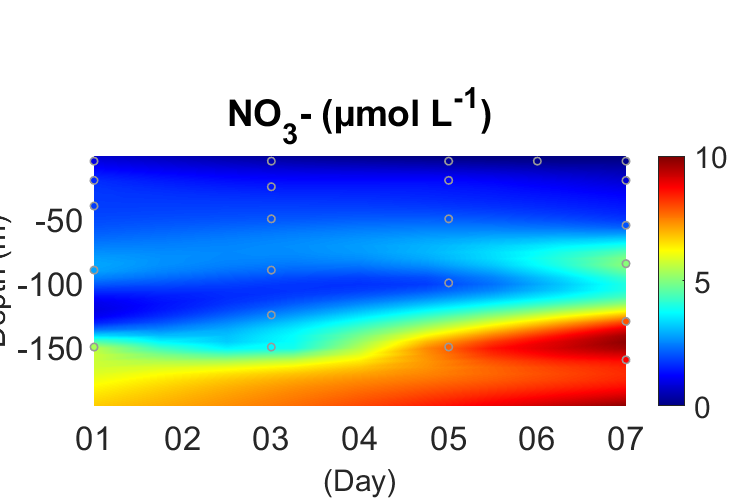

figure()

set(gcf,'PaperUnits','centimeters');
xSize=12; % Ancho
ySize=8; % Alto
xLeft=(12-xSize)/2;
yTop=(12-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

xt=1.5/xSize;
yt=1.5/ySize;
wt=(10)/xSize; % Ancho
ht=(4)/ySize; % Alto
axes('position',[xt yt wt ht]);

pcolor(dateINTS,-presINT,NO3_INT_S); %representas tu variable. primero colocas x(en mi caso date, que es el tiempo), luego y (en mi caso la presión en negativo) y luego tu variable de color (mi caso nitrato)
% shading flat; %esto es para que no te pinte una malla de cuadrados negros, así se ve más fluido el gráfico (hay otro que es interp en lugar de flat que lo suaviza mas aun)
shading interp
datetick('x','dd'); %esto tu no lo pones, porque no tienes tiempo en el eje x. para ver cómo se ponen las etiquetas, vete al otro que te pasé, al de cris
% xlim([dateN_I01(1)-0.008 dateN_I01(end)+0.08]); %esto no hace falta, es para eliminar huecos en blanco alrededor del gráfico. lo ajustas al valor máximo y mínimo de tus variables x e y
% ylim([-34.5 0]);

title ({'NO_{3}^ - (µmol L^-^1)'});
ax=gca;
ax.FontSize = 20;
ylabel('Depth (m)', 'FontSize',18); %nombre de los ejes
xlab=xlabel('(Day)', 'FontSize',18);

colormap('jet'); cb=colorbar;
caxis([0 10]);  % masximos y minomos de la escala

hold on; %para superponer los puntos donde se cogió muestra de agua para medir nitrato:
scatter(dateSN(isfinite(NO3NS)),-depthS(isfinite(NO3NS)),20,NO3NS(isfinite(NO3NS)),'o','filled','MarkerEdgeColor',[.6 .6 .6],'LineWidth',1);

exportgraphics(gcf, 'Spring_S6_NO3.png','Resolution',300)

## NH4

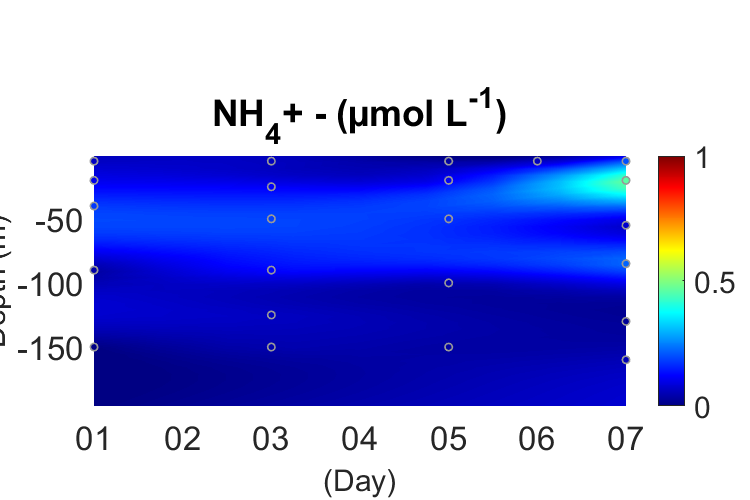

figure()

set(gcf,'PaperUnits','centimeters');
xSize=12; % Ancho
ySize=8; % Alto
xLeft=(12-xSize)/2;
yTop=(12-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

xt=1.5/xSize;
yt=1.5/ySize;
wt=(10)/xSize; % Ancho
ht=(4)/ySize; % Alto
axes('position',[xt yt wt ht]);

pcolor(dateINTS,-presINT,NH4_INT_S); %representas tu variable. primero colocas x(en mi caso date, que es el tiempo), luego y (en mi caso la presión en negativo) y luego tu variable de color (mi caso nitrato)
% shading flat; %esto es para que no te pinte una malla de cuadrados negros, así se ve más fluido el gráfico (hay otro que es interp en lugar de flat que lo suaviza mas aun)
shading interp
datetick('x','dd'); %esto tu no lo pones, porque no tienes tiempo en el eje x. para ver cómo se ponen las etiquetas, vete al otro que te pasé, al de cris
% xlim([dateN_I01(1)-0.008 dateN_I01(end)+0.08]); %esto no hace falta, es para eliminar huecos en blanco alrededor del gráfico. lo ajustas al valor máximo y mínimo de tus variables x e y
% ylim([-34.5 0]);

title ({'NH_{4}^ + - (µmol L^-^1)'});
ax=gca;
ax.FontSize = 20;
ylabel('Depth (m)', 'FontSize',18); %nombre de los ejes
xlab=xlabel('(Day)', 'FontSize',18);

colormap('jet'); cb=colorbar;
caxis([0 1]);  % masximos y minomos de la escala

hold on; %para superponer los puntos donde se cogió muestra de agua para medir nitrato:
scatter(dateSN(isfinite(NH4NS)),-depthS(isfinite(NH4NS)),20,NH4NS(isfinite(NH4NS)),'o','filled','MarkerEdgeColor',[.6 .6 .6],'LineWidth',1);

exportgraphics(gcf, 'Spring_S6_NH4.png','Resolution',300)

## TIN

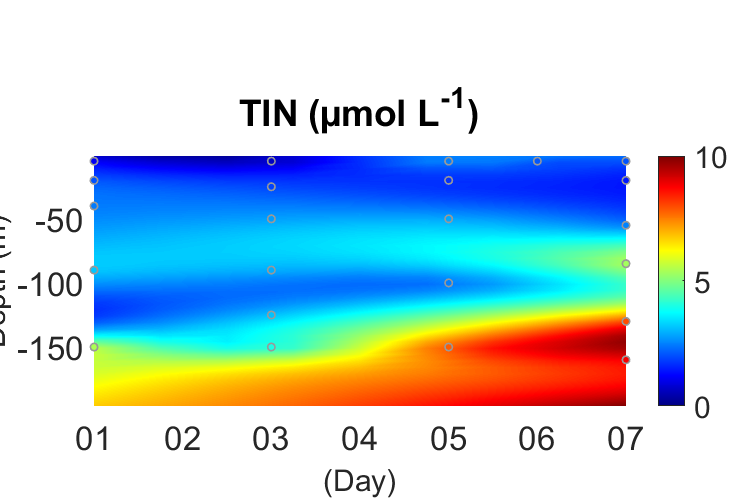

figure()

set(gcf,'PaperUnits','centimeters');
xSize=12; % Ancho
ySize=8; % Alto
xLeft=(12-xSize)/2;
yTop=(12-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

xt=1.5/xSize;
yt=1.5/ySize;
wt=(10)/xSize; % Ancho
ht=(4)/ySize; % Alto
axes('position',[xt yt wt ht]);

pcolor(dateINTS,-presINT,TIN_INT_S); %representas tu variable. primero colocas x(en mi caso date, que es el tiempo), luego y (en mi caso la presión en negativo) y luego tu variable de color (mi caso nitrato)
% shading flat; %esto es para que no te pinte una malla de cuadrados negros, así se ve más fluido el gráfico (hay otro que es interp en lugar de flat que lo suaviza mas aun)
shading interp
datetick('x','dd'); %esto tu no lo pones, porque no tienes tiempo en el eje x. para ver cómo se ponen las etiquetas, vete al otro que te pasé, al de cris
% xlim([dateN_I01(1)-0.008 dateN_I01(end)+0.08]); %esto no hace falta, es para eliminar huecos en blanco alrededor del gráfico. lo ajustas al valor máximo y mínimo de tus variables x e y
% ylim([-34.5 0]);

title ({'TIN_{ }(µmol L^-^1)'});
ax=gca;
ax.FontSize = 20;
ylabel('Depth (m)', 'FontSize',18); %nombre de los ejes
xlab=xlabel('(Day)', 'FontSize',18);

colormap('jet'); cb=colorbar;
caxis([0 10]);  % masximos y minomos de la escala

hold on; %para superponer los puntos donde se cogió muestra de agua para medir nitrato:
scatter(dateSN(isfinite(TINS)),-depthS(isfinite(TINS)),20,TINS(isfinite(TINS)),'o','filled','MarkerEdgeColor',[.6 .6 .6],'LineWidth',1);

exportgraphics(gcf, 'Spring_S6_TIN.png','Resolution',300)

## PO4

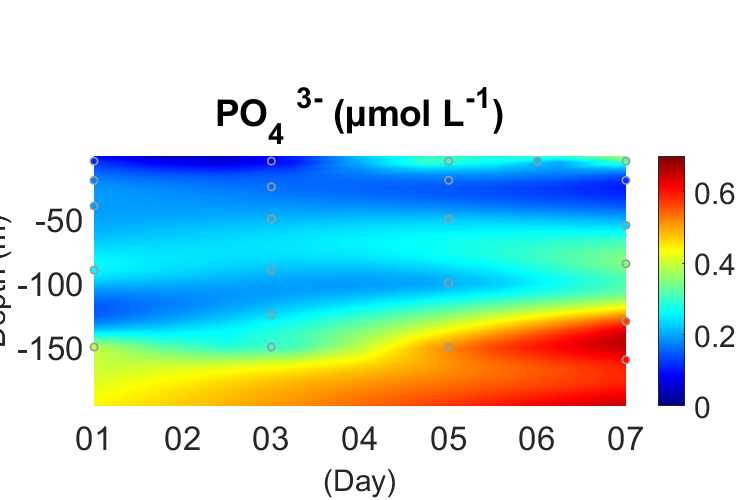

figure()

set(gcf,'PaperUnits','centimeters');
xSize=12; % Ancho
ySize=8; % Alto
xLeft=(12-xSize)/2;
yTop=(12-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

xt=1.5/xSize;
yt=1.5/ySize;
wt=(10)/xSize; % Ancho
ht=(4)/ySize; % Alto
axes('position',[xt yt wt ht]);

pcolor(dateINTS,-presINT,PO4_INT_S); %representas tu variable. primero colocas x(en mi caso date, que es el tiempo), luego y (en mi caso la presión en negativo) y luego tu variable de color (mi caso nitrato)
% shading flat; %esto es para que no te pinte una malla de cuadrados negros, así se ve más fluido el gráfico (hay otro que es interp en lugar de flat que lo suaviza mas aun)
shading interp
datetick('x','dd'); %esto tu no lo pones, porque no tienes tiempo en el eje x. para ver cómo se ponen las etiquetas, vete al otro que te pasé, al de cris
% xlim([dateN_I01(1)-0.008 dateN_I01(end)+0.08]); %esto no hace falta, es para eliminar huecos en blanco alrededor del gráfico. lo ajustas al valor máximo y mínimo de tus variables x e y
% ylim([-34.5 0]);

title ({'PO_{4} ^3^- (µmol L^-^1)'});
ax=gca;
ax.FontSize = 20;
ylabel('Depth (m)', 'FontSize',18); %nombre de los ejes
xlab=xlabel('(Day)', 'FontSize',18);

colormap('jet'); cb=colorbar;
caxis([0 0.7]);  % masximos y minomos de la escala

hold on; %para superponer los puntos donde se cogió muestra de agua para medir nitrato:
scatter(dateSN(isfinite(PO4NS)),-depthS(isfinite(PO4NS)),20,PO4NS(isfinite(PO4NS)),'o','filled','MarkerEdgeColor',[.6 .6 .6],'LineWidth',1);

exportgraphics(gcf, 'Spring_S6_PO4.png','Resolution',300)

## SiO2

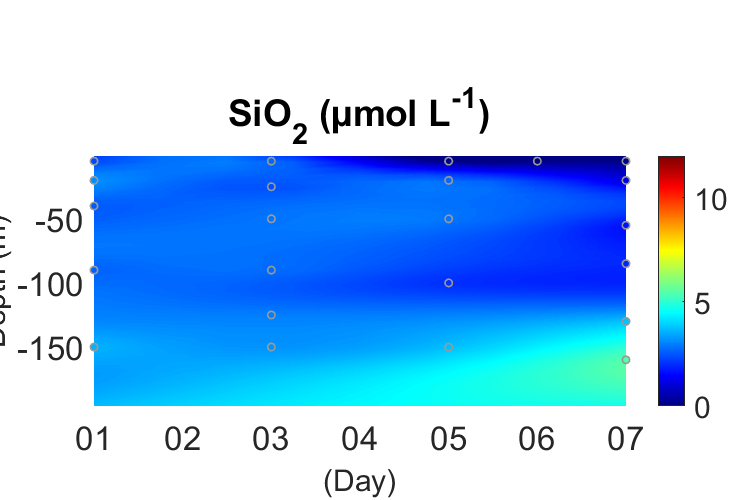

figure()

set(gcf,'PaperUnits','centimeters');
xSize=12; % Ancho
ySize=8; % Alto
xLeft=(12-xSize)/2;
yTop=(12-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

xt=1.5/xSize;
yt=1.5/ySize;
wt=(10)/xSize; % Ancho
ht=(4)/ySize; % Alto
axes('position',[xt yt wt ht]);

pcolor(dateINTS,-presINT,SiO2_INT_S); %representas tu variable. primero colocas x(en mi caso date, que es el tiempo), luego y (en mi caso la presión en negativo) y luego tu variable de color (mi caso nitrato)
% shading flat; %esto es para que no te pinte una malla de cuadrados negros, así se ve más fluido el gráfico (hay otro que es interp en lugar de flat que lo suaviza mas aun)
shading interp
datetick('x','dd'); %esto tu no lo pones, porque no tienes tiempo en el eje x. para ver cómo se ponen las etiquetas, vete al otro que te pasé, al de cris
% xlim([dateN_I01(1)-0.008 dateN_I01(end)+0.08]); %esto no hace falta, es para eliminar huecos en blanco alrededor del gráfico. lo ajustas al valor máximo y mínimo de tus variables x e y
% ylim([-34.5 0]);

title ({'SiO_{2} (µmol L^-^1)'});
ax=gca;
ax.FontSize = 20;
ylabel('Depth (m)', 'FontSize',18); %nombre de los ejes
xlab=xlabel('(Day)', 'FontSize',18);

colormap('jet'); cb=colorbar;
caxis([0 12]);  % masximos y minomos de la escala

hold on; %para superponer los puntos donde se cogió muestra de agua para medir nitrato:
scatter(dateSN(isfinite(SiO2NS)),-depthS(isfinite(SiO2NS)),20,SiO2NS(isfinite(SiO2NS)),'o','filled','MarkerEdgeColor',[.6 .6 .6],'LineWidth',1);

exportgraphics(gcf, 'Spring_S6_SiO2.png','Resolution',300)

## Clorofola Total

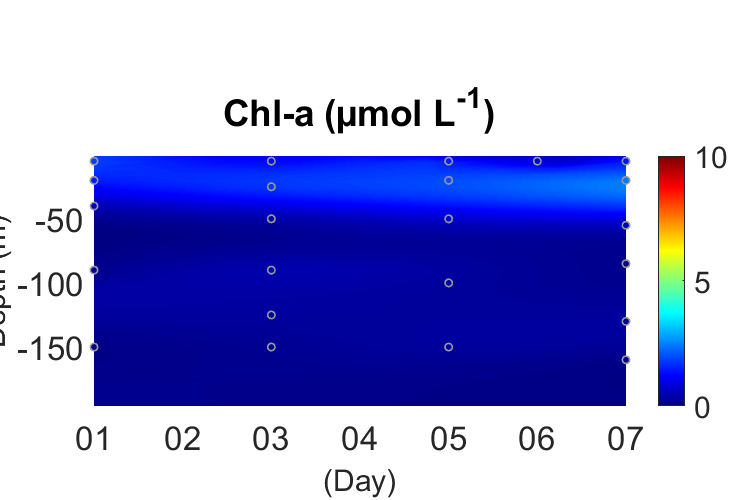

figure()

set(gcf,'PaperUnits','centimeters');
xSize=12; % Ancho
ySize=8; % Alto
xLeft=(12-xSize)/2;
yTop=(12-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

xt=1.5/xSize;
yt=1.5/ySize;
wt=(10)/xSize; % Ancho
ht=(4)/ySize; % Alto
axes('position',[xt yt wt ht]);

pcolor(dateINTS,-presINT,TChla_INT_S); %representas tu variable. primero colocas x(en mi caso date, que es el tiempo), luego y (en mi caso la presión en negativo) y luego tu variable de color (mi caso nitrato)
% shading flat; %esto es para que no te pinte una malla de cuadrados negros, así se ve más fluido el gráfico (hay otro que es interp en lugar de flat que lo suaviza mas aun)
shading interp
datetick('x','dd'); %esto tu no lo pones, porque no tienes tiempo en el eje x. para ver cómo se ponen las etiquetas, vete al otro que te pasé, al de cris
% xlim([dateN_I01(1)-0.008 dateN_I01(end)+0.08]); %esto no hace falta, es para eliminar huecos en blanco alrededor del gráfico. lo ajustas al valor máximo y mínimo de tus variables x e y
% ylim([-34.5 0]);

title ({'Chl-a_{ }(µmol L^-^1)'});
ax=gca;
ax.FontSize = 20;
ylabel('Depth (m)', 'FontSize',18); %nombre de los ejes
xlab=xlabel('(Day)', 'FontSize',18);
colormap('jet'); cb=colorbar;
caxis([0 10]);  % masximos y minomos de la escala

hold on; %para superponer los puntos donde se cogió muestra de agua para medir nitrato:
scatter(dateSN(isfinite(TChlaNS)),-depthS(isfinite(TChlaNS)),20,TChlaNS(isfinite(TChlaNS)),'o','filled','MarkerEdgeColor',[.6 .6 .6],'LineWidth',1);

exportgraphics(gcf, 'Spring_S6_Chl-a.png','Resolution',300)

## Verano

## NO2

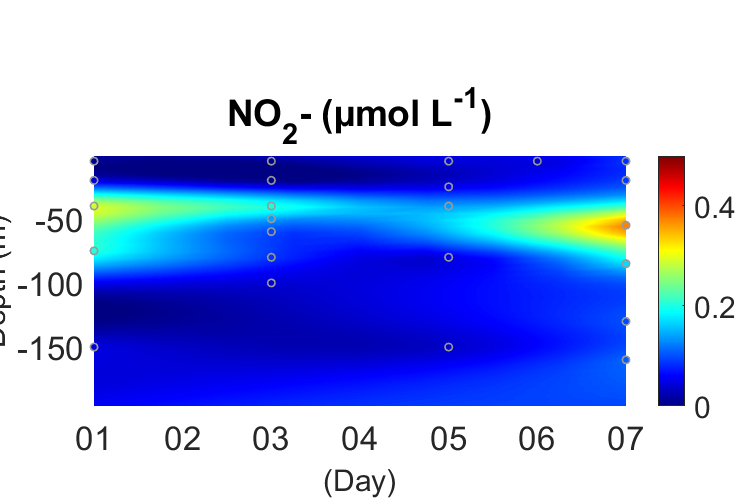

figure()

set(gcf,'PaperUnits','centimeters');
xSize=12; % Ancho
ySize=8; % Alto
xLeft=(12-xSize)/2;
yTop=(12-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

xt=1.5/xSize;
yt=1.5/ySize;
wt=(10)/xSize; % Ancho
ht=(4)/ySize; % Alto
axes('position',[xt yt wt ht]);

pcolor(dateINTSM,-presINT,NO2_INT_SM); %representas tu variable. primero colocas x(en mi caso date, que es el tiempo), luego y (en mi caso la presión en negativo) y luego tu variable de color (mi caso nitrato)
% shading flat; %esto es para que no te pinte una malla de cuadrados negros, así se ve más fluido el gráfico (hay otro que es interp en lugar de flat que lo suaviza mas aun)
shading interp
datetick('x','dd'); %esto tu no lo pones, porque no tienes tiempo en el eje x. para ver cómo se ponen las etiquetas, vete al otro que te pasé, al de cris
% xlim([dateN_I01(1)-0.008 dateN_I01(end)+0.08]); %esto no hace falta, es para eliminar huecos en blanco alrededor del gráfico. lo ajustas al valor máximo y mínimo de tus variables x e y
% ylim([-34.5 0]);

title ({'NO_{2}^ - (µmol L^-^1)'});
ax=gca;
ax.FontSize = 20;
ylabel('Depth (m)', 'FontSize',18); %nombre de los ejes
xlab=xlabel('(Day)', 'FontSize',18);

colormap('jet'); cb=colorbar;
caxis([0 0.5]);  % masximos y minomos de la escala

hold on; %para superponer los puntos donde se cogió muestra de agua para medir nitrato:
scatter(dateSMN(isfinite(NO2NSM)),-depthSM(isfinite(NO2NSM)),20,NO2NSM(isfinite(NO2NSM)),'o','filled','MarkerEdgeColor',[.6 .6 .6],'LineWidth',1);

exportgraphics(gcf, 'Summer_S6_NO2.png','Resolution',300)

## NO3

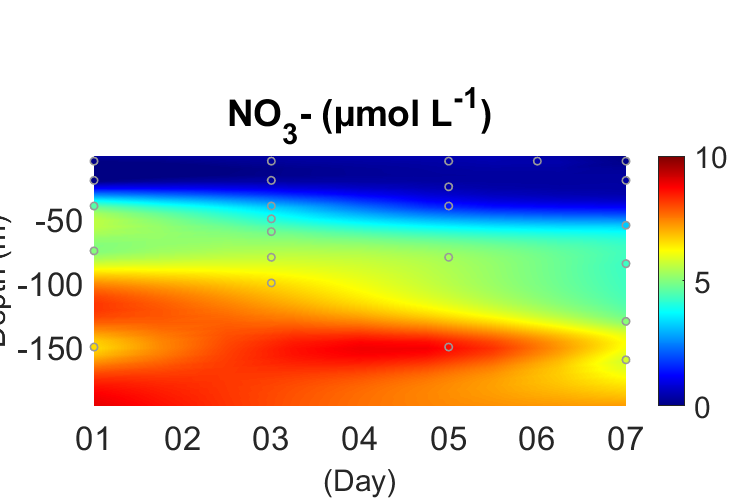

figure()

set(gcf,'PaperUnits','centimeters');
xSize=12; % Ancho
ySize=8; % Alto
xLeft=(12-xSize)/2;
yTop=(12-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

xt=1.5/xSize;
yt=1.5/ySize;
wt=(10)/xSize; % Ancho
ht=(4)/ySize; % Alto
axes('position',[xt yt wt ht]);

pcolor(dateINTSM,-presINT,NO3_INT_SM); %representas tu variable. primero colocas x(en mi caso date, que es el tiempo), luego y (en mi caso la presión en negativo) y luego tu variable de color (mi caso nitrato)
% shading flat; %esto es para que no te pinte una malla de cuadrados negros, así se ve más fluido el gráfico (hay otro que es interp en lugar de flat que lo suaviza mas aun)
shading interp
datetick('x','dd'); %esto tu no lo pones, porque no tienes tiempo en el eje x. para ver cómo se ponen las etiquetas, vete al otro que te pasé, al de cris
% xlim([dateN_I01(1)-0.008 dateN_I01(end)+0.08]); %esto no hace falta, es para eliminar huecos en blanco alrededor del gráfico. lo ajustas al valor máximo y mínimo de tus variables x e y
% ylim([-34.5 0]);

title ({'NO_{3}^ - (µmol L^-^1)'});
ax=gca;
ax.FontSize = 20;
ylabel('Depth (m)', 'FontSize',18); %nombre de los ejes
xlab=xlabel('(Day)', 'FontSize',18);

colormap('jet'); cb=colorbar;
caxis([0 10]);  % masximos y minomos de la escala

hold on; %para superponer los puntos donde se cogió muestra de agua para medir nitrato:
scatter(dateSMN(isfinite(NO3NSM)),-depthSM(isfinite(NO3NSM)),20,NO3NSM(isfinite(NO3NSM)),'o','filled','MarkerEdgeColor',[.6 .6 .6],'LineWidth',1);

exportgraphics(gcf, 'Summer_S6_NO3.png','Resolution',300)

## NH4

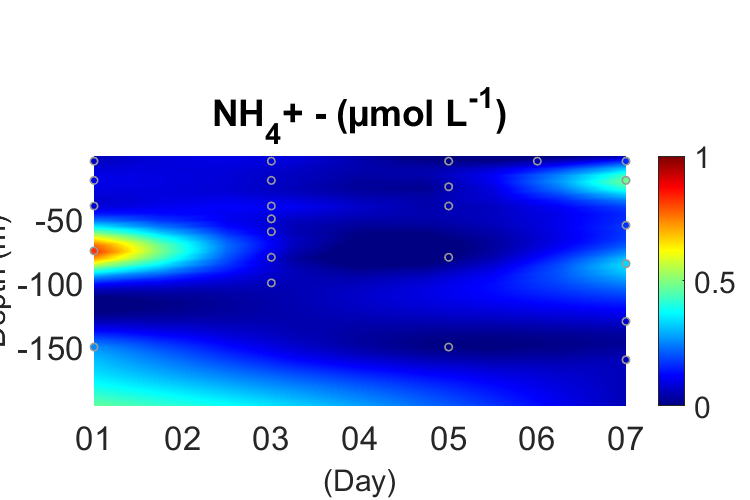

figure()

set(gcf,'PaperUnits','centimeters');
xSize=12; % Ancho
ySize=8; % Alto
xLeft=(12-xSize)/2;
yTop=(12-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

xt=1.5/xSize;
yt=1.5/ySize;
wt=(10)/xSize; % Ancho
ht=(4)/ySize; % Alto
axes('position',[xt yt wt ht]);

pcolor(dateINTSM,-presINT,NH4_INT_SM); %representas tu variable. primero colocas x(en mi caso date, que es el tiempo), luego y (en mi caso la presión en negativo) y luego tu variable de color (mi caso nitrato)
% shading flat; %esto es para que no te pinte una malla de cuadrados negros, así se ve más fluido el gráfico (hay otro que es interp en lugar de flat que lo suaviza mas aun)
shading interp
datetick('x','dd'); %esto tu no lo pones, porque no tienes tiempo en el eje x. para ver cómo se ponen las etiquetas, vete al otro que te pasé, al de cris
% xlim([dateN_I01(1)-0.008 dateN_I01(end)+0.08]); %esto no hace falta, es para eliminar huecos en blanco alrededor del gráfico. lo ajustas al valor máximo y mínimo de tus variables x e y
% ylim([-34.5 0]);

title ({'NH_{4}^ + - (µmol L^-^1)'});
ax=gca;
ax.FontSize = 20;
ylabel('Depth (m)', 'FontSize',18); %nombre de los ejes
xlab=xlabel('(Day)', 'FontSize',18);

colormap('jet'); cb=colorbar;
caxis([0 1]);  % masximos y minomos de la escala

hold on; %para superponer los puntos donde se cogió muestra de agua para medir nitrato:
scatter(dateSMN(isfinite(NH4NSM)),-depthSM(isfinite(NH4NSM)),20,NH4NSM(isfinite(NH4NSM)),'o','filled','MarkerEdgeColor',[.6 .6 .6],'LineWidth',1);

exportgraphics(gcf, 'Summer_S6_NH4.png','Resolution',300)

## TIN

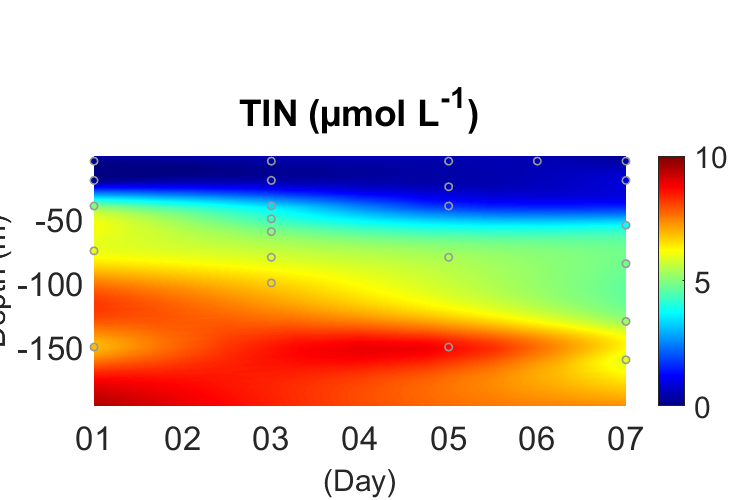

figure()

set(gcf,'PaperUnits','centimeters');
xSize=12; % Ancho
ySize=8; % Alto
xLeft=(12-xSize)/2;
yTop=(12-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

xt=1.5/xSize;
yt=1.5/ySize;
wt=(10)/xSize; % Ancho
ht=(4)/ySize; % Alto
axes('position',[xt yt wt ht]);

pcolor(dateINTSM,-presINT,TIN_INT_SM); %representas tu variable. primero colocas x(en mi caso date, que es el tiempo), luego y (en mi caso la presión en negativo) y luego tu variable de color (mi caso nitrato)
% shading flat; %esto es para que no te pinte una malla de cuadrados negros, así se ve más fluido el gráfico (hay otro que es interp en lugar de flat que lo suaviza mas aun)
shading interp
datetick('x','dd'); %esto tu no lo pones, porque no tienes tiempo en el eje x. para ver cómo se ponen las etiquetas, vete al otro que te pasé, al de cris
% xlim([dateN_I01(1)-0.008 dateN_I01(end)+0.08]); %esto no hace falta, es para eliminar huecos en blanco alrededor del gráfico. lo ajustas al valor máximo y mínimo de tus variables x e y
% ylim([-34.5 0]);

title ({'TIN_{ }(µmol L^-^1)'});
ax=gca;
ax.FontSize = 20;
ylabel('Depth (m)', 'FontSize',18); %nombre de los ejes
xlab=xlabel('(Day)', 'FontSize',18);

colormap('jet'); cb=colorbar;
caxis([0 10]);  % masximos y minomos de la escala

hold on; %para superponer los puntos donde se cogió muestra de agua para medir nitrato:
scatter(dateSMN(isfinite(TINSM)),-depthSM(isfinite(TINSM)),20,TINSM(isfinite(TINSM)),'o','filled','MarkerEdgeColor',[.6 .6 .6],'LineWidth',1);

exportgraphics(gcf, 'Summer_S6_TIN.png','Resolution',300)

## PO4

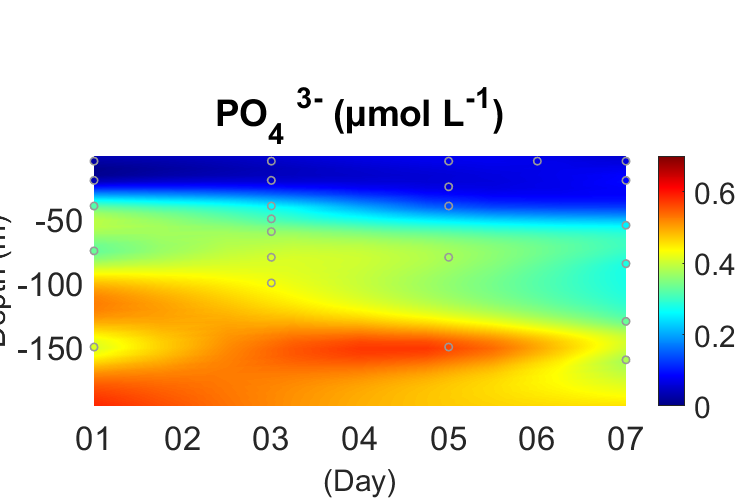

figure()

set(gcf,'PaperUnits','centimeters');
xSize=12; % Ancho
ySize=8; % Alto
xLeft=(12-xSize)/2;
yTop=(12-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

xt=1.5/xSize;
yt=1.5/ySize;
wt=(10)/xSize; % Ancho
ht=(4)/ySize; % Alto
axes('position',[xt yt wt ht]);

pcolor(dateINTSM,-presINT,PO4_INT_SM); %representas tu variable. primero colocas x(en mi caso date, que es el tiempo), luego y (en mi caso la presión en negativo) y luego tu variable de color (mi caso nitrato)
% shading flat; %esto es para que no te pinte una malla de cuadrados negros, así se ve más fluido el gráfico (hay otro que es interp en lugar de flat que lo suaviza mas aun)
shading interp
datetick('x','dd'); %esto tu no lo pones, porque no tienes tiempo en el eje x. para ver cómo se ponen las etiquetas, vete al otro que te pasé, al de cris
% xlim([dateN_I01(1)-0.008 dateN_I01(end)+0.08]); %esto no hace falta, es para eliminar huecos en blanco alrededor del gráfico. lo ajustas al valor máximo y mínimo de tus variables x e y
% ylim([-34.5 0]);

title ({'PO_{4} ^3^- (µmol L^-^1)'});
ax=gca;
ax.FontSize = 20;
ylabel('Depth (m)', 'FontSize',18); %nombre de los ejes
xlab=xlabel('(Day)', 'FontSize',18);

colormap('jet'); cb=colorbar;
caxis([0 0.7]);  % masximos y minomos de la escala

hold on; %para superponer los puntos donde se cogió muestra de agua para medir nitrato:
scatter(dateSMN(isfinite(PO4NSM)),-depthSM(isfinite(PO4NSM)),20,PO4NSM(isfinite(PO4NSM)),'o','filled','MarkerEdgeColor',[.6 .6 .6],'LineWidth',1);

exportgraphics(gcf, 'Summer_S6_PO4.png','Resolution',300)

## SiO2

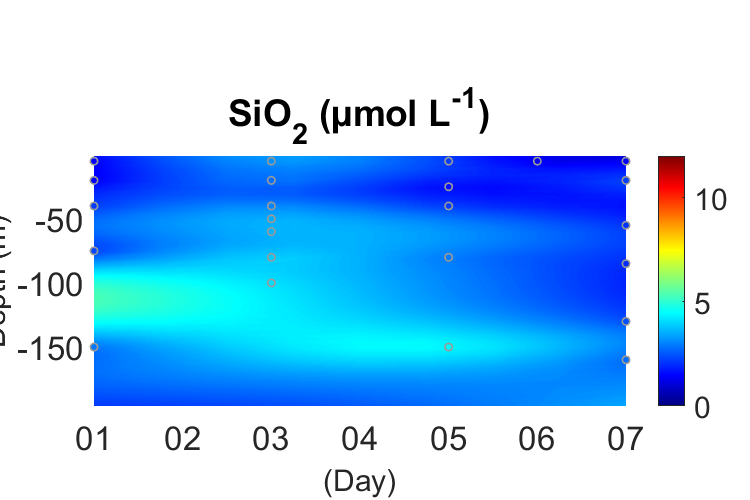

figure()

set(gcf,'PaperUnits','centimeters');
xSize=12; % Ancho
ySize=8; % Alto
xLeft=(12-xSize)/2;
yTop=(12-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

xt=1.5/xSize;
yt=1.5/ySize;
wt=(10)/xSize; % Ancho
ht=(4)/ySize; % Alto
axes('position',[xt yt wt ht]);

pcolor(dateINTSM,-presINT,SiO2_INT_SM); %representas tu variable. primero colocas x(en mi caso date, que es el tiempo), luego y (en mi caso la presión en negativo) y luego tu variable de color (mi caso nitrato)
% shading flat; %esto es para que no te pinte una malla de cuadrados negros, así se ve más fluido el gráfico (hay otro que es interp en lugar de flat que lo suaviza mas aun)
shading interp
datetick('x','dd'); %esto tu no lo pones, porque no tienes tiempo en el eje x. para ver cómo se ponen las etiquetas, vete al otro que te pasé, al de cris
% xlim([dateN_I01(1)-0.008 dateN_I01(end)+0.08]); %esto no hace falta, es para eliminar huecos en blanco alrededor del gráfico. lo ajustas al valor máximo y mínimo de tus variables x e y
% ylim([-34.5 0]);

title ({'SiO_{2} (µmol L^-^1)'});
ax=gca;
ax.FontSize = 20;
ylabel('Depth (m)', 'FontSize',18); %nombre de los ejes
xlab=xlabel('(Day)', 'FontSize',18);

colormap('jet'); cb=colorbar;
caxis([0 12]);  % masximos y minomos de la escala

hold on; %para superponer los puntos donde se cogió muestra de agua para medir nitrato:
scatter(dateSMN(isfinite(SiO2NSM)),-depthSM(isfinite(SiO2NSM)),20,SiO2NSM(isfinite(SiO2NSM)),'o','filled','MarkerEdgeColor',[.6 .6 .6],'LineWidth',1);

exportgraphics(gcf, 'Summer_S6_SiO2.png','Resolution',300)

## Clorofola Total

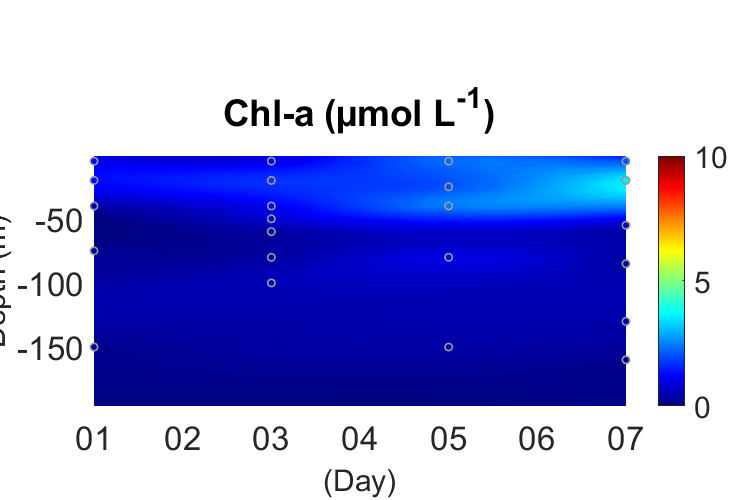

figure()

set(gcf,'PaperUnits','centimeters');
xSize=12; % Ancho
ySize=8; % Alto
xLeft=(12-xSize)/2;
yTop=(12-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

xt=1.5/xSize;
yt=1.5/ySize;
wt=(10)/xSize; % Ancho
ht=(4)/ySize; % Alto
axes('position',[xt yt wt ht]);

pcolor(dateINTSM,-presINT,TChla_INT_SM); %representas tu variable. primero colocas x(en mi caso date, que es el tiempo), luego y (en mi caso la presión en negativo) y luego tu variable de color (mi caso nitrato)
% shading flat; %esto es para que no te pinte una malla de cuadrados negros, así se ve más fluido el gráfico (hay otro que es interp en lugar de flat que lo suaviza mas aun)
shading interp
datetick('x','dd'); %esto tu no lo pones, porque no tienes tiempo en el eje x. para ver cómo se ponen las etiquetas, vete al otro que te pasé, al de cris
% xlim([dateN_I01(1)-0.008 dateN_I01(end)+0.08]); %esto no hace falta, es para eliminar huecos en blanco alrededor del gráfico. lo ajustas al valor máximo y mínimo de tus variables x e y
% ylim([-34.5 0]);33 

title ({'Chl-a_{ }(µmol L^-^1)'});
ax=gca;
ax.FontSize = 20;
ylabel('Depth (m)', 'FontSize',18); %nombre de los ejes
xlab=xlabel('(Day)', 'FontSize',18);

colormap('jet'); cb=colorbar;
caxis([0 10]);  % masximos y minomos de la escala

hold on; %para superponer los puntos donde se cogió muestra de agua para medir nitrato:
scatter(dateSMN(isfinite(TChlaNSM)),-depthSM(isfinite(TChlaNSM)),20,TChlaNSM(isfinite(TChlaNSM)),'o','filled','MarkerEdgeColor',[.6 .6 .6],'LineWidth',1);

exportgraphics(gcf, 'Summer_S6_Chl-a.png','Resolution',300)